
clear; clc; close all;


m_table = 226.8;    % kg (500 lbs)
m_load = 226.8/2;     % kg (500 lbs)
W = 1.8;            % m (Width)
H = 0.2;            % m (Thickness/Height)
target_rpm = 1;     
t_accel = 30.0;      
eta = 0.70;         % Efficiency (High reduction worm)
g = 9.81;

% Motor Specs for Inertia Matching
J_motor = 0.005;    % kg-m^2 (Typical rotor inertia)
omega_out = (target_rpm * 2 * pi) / 60;
alpha_out = omega_out / t_accel;

% Gearbox Ratios to test
N_range = 1:1:200; 
load_pos_x = [0, 0.45*W, 0.5*W]; % [Center, Mid, Edge]



for j = 1:length(load_pos_x)
    dx = load_pos_x(j);
    dy = H/2; % Load sits 10cm above the center axis
    
    % 1. Radius of Load from Axis
    r_load = sqrt(dx^2 + dy^2);
    
    % 2. Moment of Inertia (3D Block + Offset Load)
    I_table = (1/12) * m_table * (W^2 + H^2);
    I_load = m_load * r_load^2;
    I_total = I_table + I_load;
    
    % 3. Torque Components (Worst Case)
    T_accel = I_total * alpha_out;
    
    
    T_gravity_load = m_load * g * dx; % Max torque occurs when width is horizontal
    %T_gravity_load = 0
    % Friction estimate (assuming 1000lb total weight on 2.5" bearings)
    T_friction = 0.02 * (m_table + m_load) * g * 0.03175;
    %T_friction = 0
    
    T_out_total = (T_accel + T_gravity_load + T_friction) / eta
    
    fprintf('CONFIG: Load at X=%.2fm (Y-Offset = 0.1m)\n', dx);
    fprintf('  I_Table:      %10.2f kg-m^2\n', I_table);
    fprintf('  I_Load:       %10.2f kg-m^2\n', I_load);
    fprintf('  I_Total:      %10.2f kg-m^2\n', I_total);
    fprintf('  PEAK TORQUE:  %10.2f Nm (%.1f lb-ft)\n', T_out_total, T_out_total * 0.737);
    fprintf('  Output Power: %10.4f HP\n', (T_out_total * omega_out)/746);
    fprintf('----------------------------------------------------\n\n');
    
    mot_torque(:,j) = T_out_total ./ N_range;
    inf_ratio(:,j) = (I_total ./ (N_range.^2)) ./ J_motor;
end

T_out_total = 3.3423

CONFIG: Load at X=0.00m (Y-Offset = 0.1m)


  I_Table:           61.99 kg-m^2


  I_Load:             1.13 kg-m^2


  I_Total:           63.13 kg-m^2


  PEAK TORQUE:        3.34 Nm (2.5 lb-ft)


  Output Power:     0.0005 HP


----------------------------------------------------



T_out_total = 1.2910e+03

CONFIG: Load at X=0.81m (Y-Offset = 0.1m)


  I_Table:           61.99 kg-m^2


  I_Load:            75.54 kg-m^2


  I_Total:          137.53 kg-m^2


  PEAK TORQUE:     1290.98 Nm (951.5 lb-ft)


  Output Power:     0.1812 HP


----------------------------------------------------



T_out_total = 1.4341e+03

CONFIG: Load at X=0.90m (Y-Offset = 0.1m)


  I_Table:           61.99 kg-m^2


  I_Load:            92.99 kg-m^2


  I_Total:          154.98 kg-m^2


  PEAK TORQUE:     1434.10 Nm (1056.9 lb-ft)


  Output Power:     0.2013 HP


----------------------------------------------------



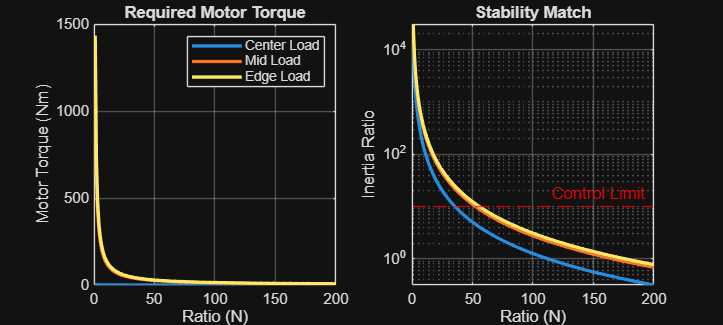

% --- Plotting ---
figure('Position', [100, 100, 1000, 450]);
subplot(1,2,1);
plot(N_range, mot_torque, 'LineWidth', 2); grid on;
xlabel('Ratio (N)'); ylabel('Motor Torque (Nm)'); title('Required Motor Torque');
legend('Center Load','Mid Load','Edge Load');

subplot(1,2,2);
semilogy(N_range, inf_ratio, 'LineWidth', 2); grid on; hold on;
yline(10, '--r', 'Control Limit');
xlabel('Ratio (N)'); ylabel('Inertia Ratio'); title('Stability Match');